% fft of data
x = [1 2 5 5 6 7 100 -100 -4 -200 -1 -2 -3 -4 5 2]'

x =      1
     2
     5
     5
     6
     7
   100
  -100
    -4
  -200


X = fft(x)

X = 	1.0e+02 *

  -1.8100 + 0.0000i
   2.2140 - 1.3532i
  -2.1955 + 1.7171i
   1.8796 - 1.4792i
  -1.0900 + 1.0000i
  -0.5210 - 0.2308i
   2.0755 - 0.3029i
  -3.3726 + 0.2552i
   3.9900 + 0.0000i
  -3.3726 - 0.2552i


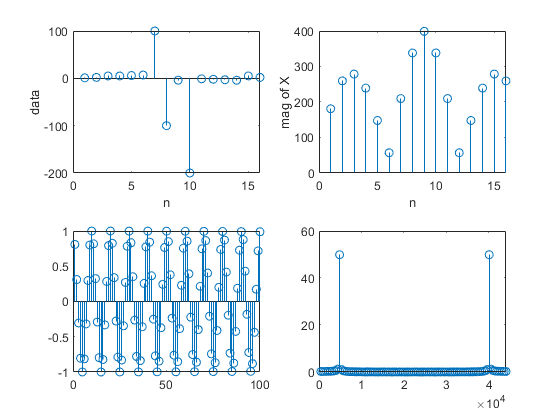

subplot(2,2,1), stem(x)
xlabel("n")
ylabel("data")
subplot(2,2,2), stem(abs(X))
xlabel ("n")
ylabel("mag of X")
% % fft of a sampled cosine
N = 100; % length of the data
n=1:N;
fs = 44100; % sampling frequency
Ts = 1/fs; % sampling period
s = cos(2*pi*4400*[n]/fs); % signal
S = fft(s); % find DFT of s
k = n; % index for frequency/DFT
freq = k*fs/N; % frequency in Hz
subplot(2,2,3), stem(s)
subplot(2,2,4), stem(freq, abs(S))